Declaramos las variables.

syms x
f = x^3 - 5*x^2 + 7*x - 3;
xest = 0;
ermax = 1e-5;

Dibujamos la función para hacernos una idea del problema que estamos resolviendo.

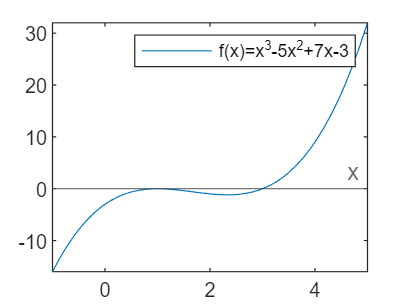

fplot(f, [-1, 5])
hold on
yline(0, '-', 'x')
legend({'f(x)=x^{3}-5x^{2}+7x-3'})
hold off

Calculamos la raíz próxima a cero con ambos métodos.

% Función Newton-Rapson modificada
[r_mod, i_mod] = newtonmod(f, xest, ermax);
% Función de clase
[r_clase, i_clase] = newton_rapson_tol_sol( ...
    matlabFunction(f), ...
    matlabFunction(diff(f)), ...
    xest, ermax);

Mostramos los resultados con 6 decimales.

fprintf("Raíz método clase: %.6f", r_clase);

Raiz método clase: 0.999994

fprintf("Se han requerido %d iteraciones.", i_clase);

Se han requerido 18 iteraciones.

fprintf("Raíz método modificado: %.6f", r_mod);

Raiz método modificado: 0.972707

fprintf("Se han requerido %d iteraciones.", i_mod);

Se han requerido 1454 iteraciones.

Gráficamente:

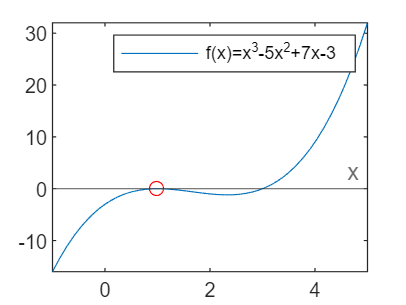

fplot(f, [-1, 5])
fx = matlabFunction(f);
hold on
plot(r_mod, fx(r_mod), 'ro')
yline(0, '-', 'x')
legend({'f(x)=x^{3}-5x^{2}+7x-3'})
hold off

Calculamos el porcentaje en el que difieren:

dif_r = abs((r_mod - r_clase) / r_clase) * 100;
fprintf("Las raíces calculadas difieren en un %.2f%%", dif_r);

Las raíces calculadas difieren en un 2.73%